# ECE1150 ASSIGNMENT6

Yinhao Qian @ University of Pittsburgh

%please ignore this block
answer = @(num,unit) fprintf(" ANSWER: %s [%s]" + ...
    " \n",mat2str(num),unit);
question = @() eval("clearvars -except answer question");

# P1-A

Preamble: allows receiver to differentiate actual packet from noise and sync with sender.

SFD: indicates start of frame.

Source and Destination Address: contains the MAC address of source and destination,

Length: number of bytes it gets after sfd and last four bytes are taken for CRC if less than 1518, and types of packets if greater than 1518.

Data: typically IP packets.

FCS: 32 bits CRC value, aka the frame check sequence.

# P1-B

the Medium Access Control is 48 bits in length, and all 1's address is predefined to be the broadcast address on the local area network. The first 24 bits are organizationally unique identifiers assigned byu the IEEE, and the second 24 bits are assigned by the manufacturer for each network interface card.

# P1-C

The binary exponential backoff says if a frame experiences m collisions, a node choose value k at random from the set {0,1,2,3,...,2^m-1}, which means as frame experience more collisions the larger the interval from which k is chosen. It is necessary because the backoff helps enforce fair distribution of access to network resources and reduce network congestions. 

# P1-D

question();
m = 5;
set = 0:1:2^m-1;
ave = sum(set)/size(set,2);
answer(ave,"");

 ANSWER: 15.5 [] 


# P1-E

question();
m = 6;
set = 0:1:2^m-1;
ave = sum(set)/size(set,2);
answer(ave,"");

 ANSWER: 31.5 [] 


# P2-A

question();
table_main = containers.Map();
table_main('B')='1';
table_main('E')='2';
table_main('H')='3';
disp([table_main.keys',table_main.values']);

    {'B'}    {'1'}
    {'E'}    {'2'}
    {'H'}    {'3'}



Please refer to the function definitions at the end of file:

The switch works like a cache. It saves the source MAC address and corresponding interface in table if not there. The switch then reads the desitnation MAC address. 

If found, foward the frame to the corresponding interface. If not found, broadcasts frame to all devices like a hub.

Transmitting A to G:

table_main = transmit('G','3',table_main);

Cache miss from table, create pair {G,3}.
    {'B'}    {'1'}
    {'E'}    {'2'}
    {'G'}    {'3'}
    {'H'}    {'3'}



Transmitting G to A:

table_main = transmit('A','1',table_main);

Cache miss from table, create pair {A,1}.
    {'A'}    {'1'}
    {'B'}    {'1'}
    {'E'}    {'2'}
    {'G'}    {'3'}
    {'H'}    {'3'}



# P2-B

question();
table_main = containers.Map();
table_x = containers.Map();
table_y = containers.Map();
table_z = containers.Map();
table_main('B')='x1';
table_main('E')='y1';
table_main('H')='z1';
disp([table_main.keys',table_main.values']);

    {'B'}    {'x1'}
    {'E'}    {'y1'}
    {'H'}    {'z1'}



table_main = transmit('G','z1',table_main);

Cache miss from table, create pair {G,z1}.
    {'B'}    {'x1'}
    {'E'}    {'y1'}
    {'G'}    {'z1'}
    {'H'}    {'z1'}



table_z = transmit('G','z2',table_z);

Cache miss from table, create pair {G,z2}.
    {'G'}    {'z2'}



table_main = transmit('A','x1',table_main);

Cache miss from table, create pair {A,x1}.
    {'A'}    {'x1'}
    {'B'}    {'x1'}
    {'E'}    {'y1'}
    {'G'}    {'z1'}
    {'H'}    {'z1'}



table_x = transmit('A','x2',table_x);

Cache miss from table, create pair {A,x2}.
    {'A'}    {'x2'}



The above is simply repeating the steps in part (a), now let's transmit from A to G again:

table_main = transmit('G','z1',table_main);

Cache hit from table.
    {'A'}    {'x1'}
    {'B'}    {'x1'}
    {'E'}    {'y1'}
    {'G'}    {'z1'}
    {'H'}    {'z1'}



table_z = transmit('G','z2',table_z);

Cache hit from table.
    {'G'}    {'z2'}



Table Y is unused. 

# P3-A

CSMA/CA DCF stands for Distributed Coordination Function. It waits for a period of time called DIFS, transmit if channel is still idle, then wait for ACK (similar to stop-and-wait ARQ).

CSMA/CA PCF stands for Point Coordination Function. Device wishing to transmit first sends Request To Send (RTS) to the AP, specifiying the duration of the requested transmittion. If no other device is tranmitting, the AP replies with Clear to Send (CTS) specifying the duration. All devices hear the CTS and will not transmit.

# P3-B

openExample('comm/ALOHAAndCSMACAPacketizedNetworkExample');

# P3-C-1

Using the ALOHA model:

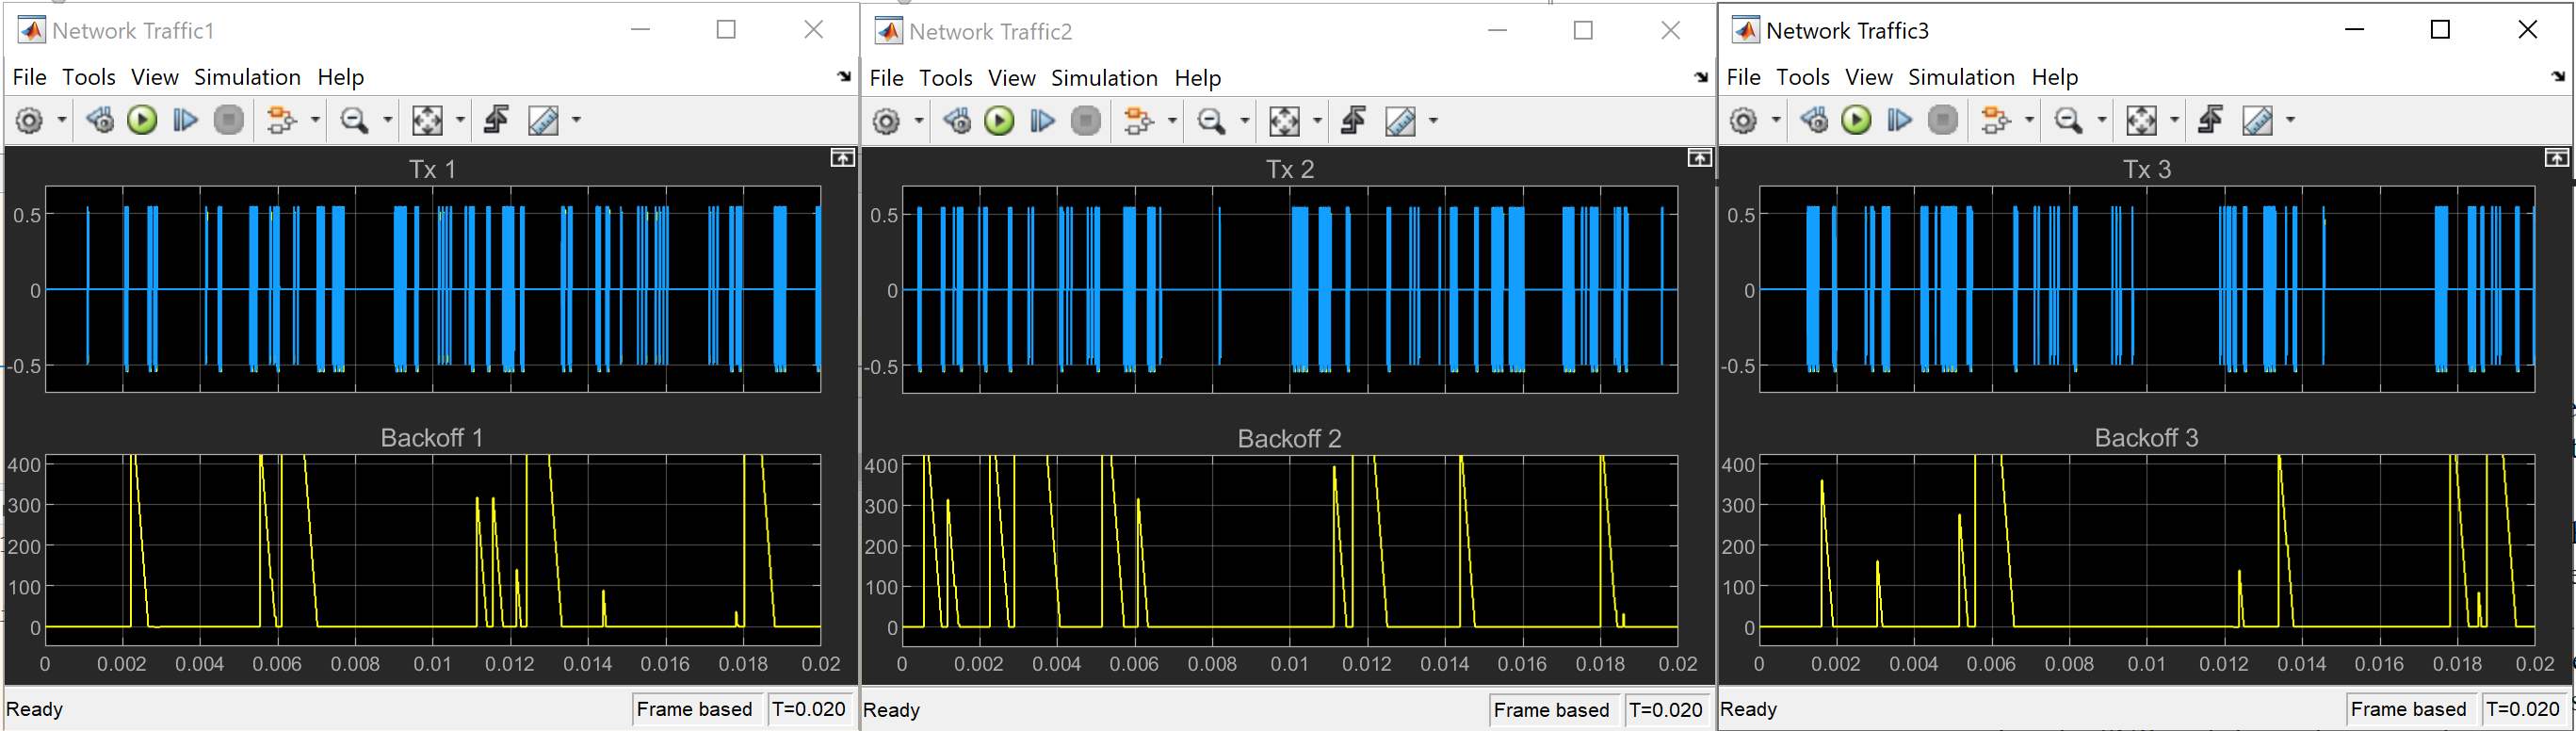

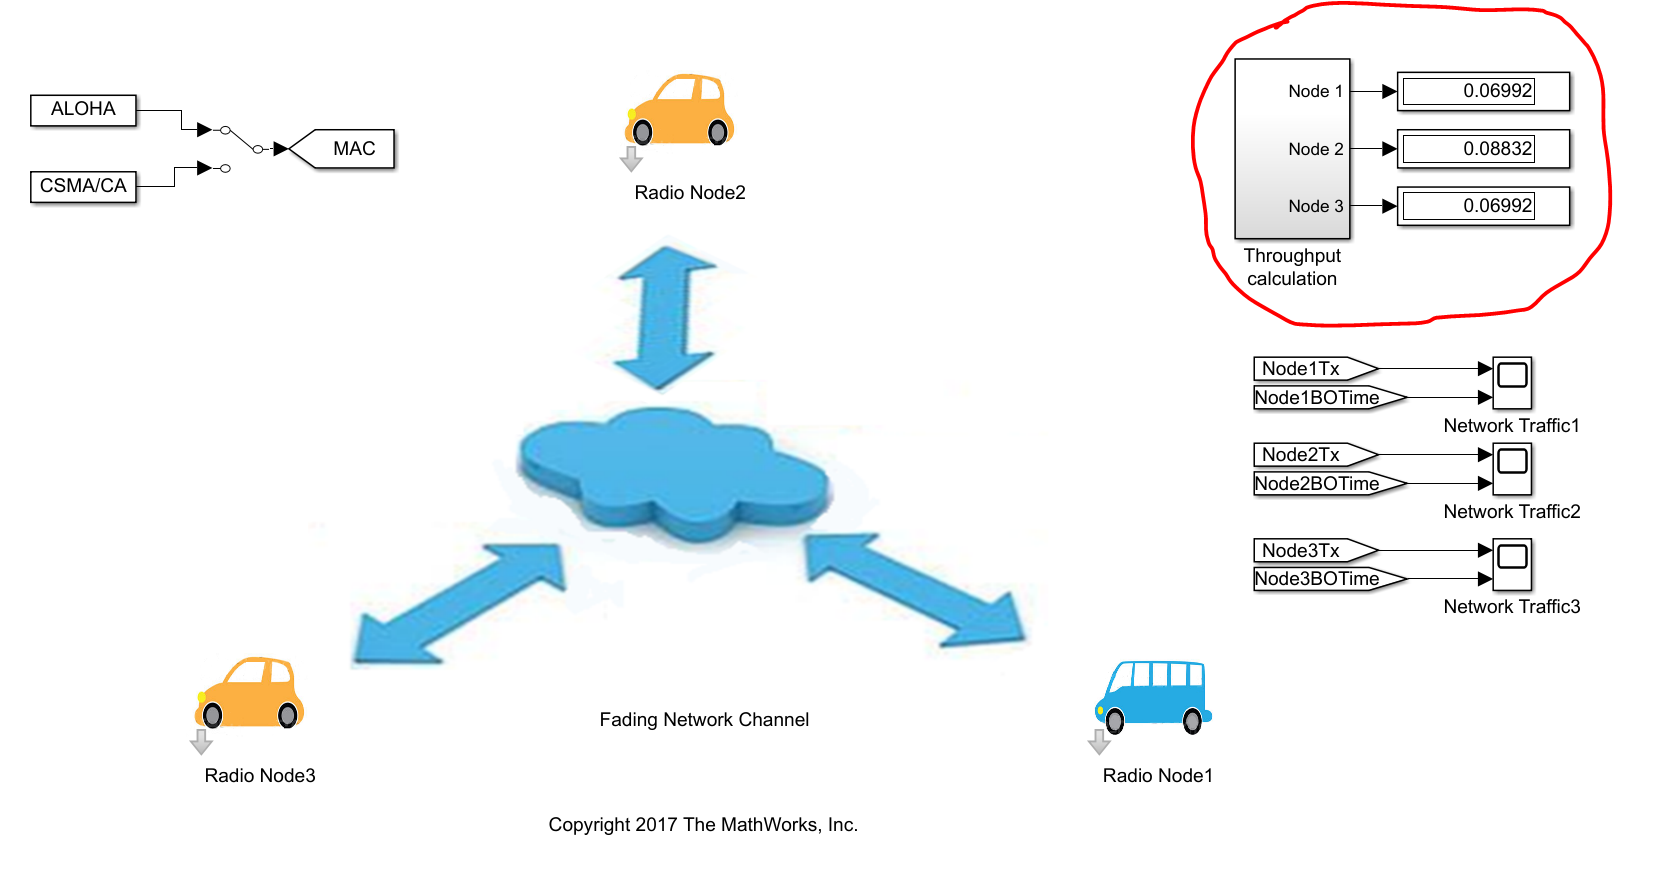

# P3-C-2

Using the CSMA/CA model:

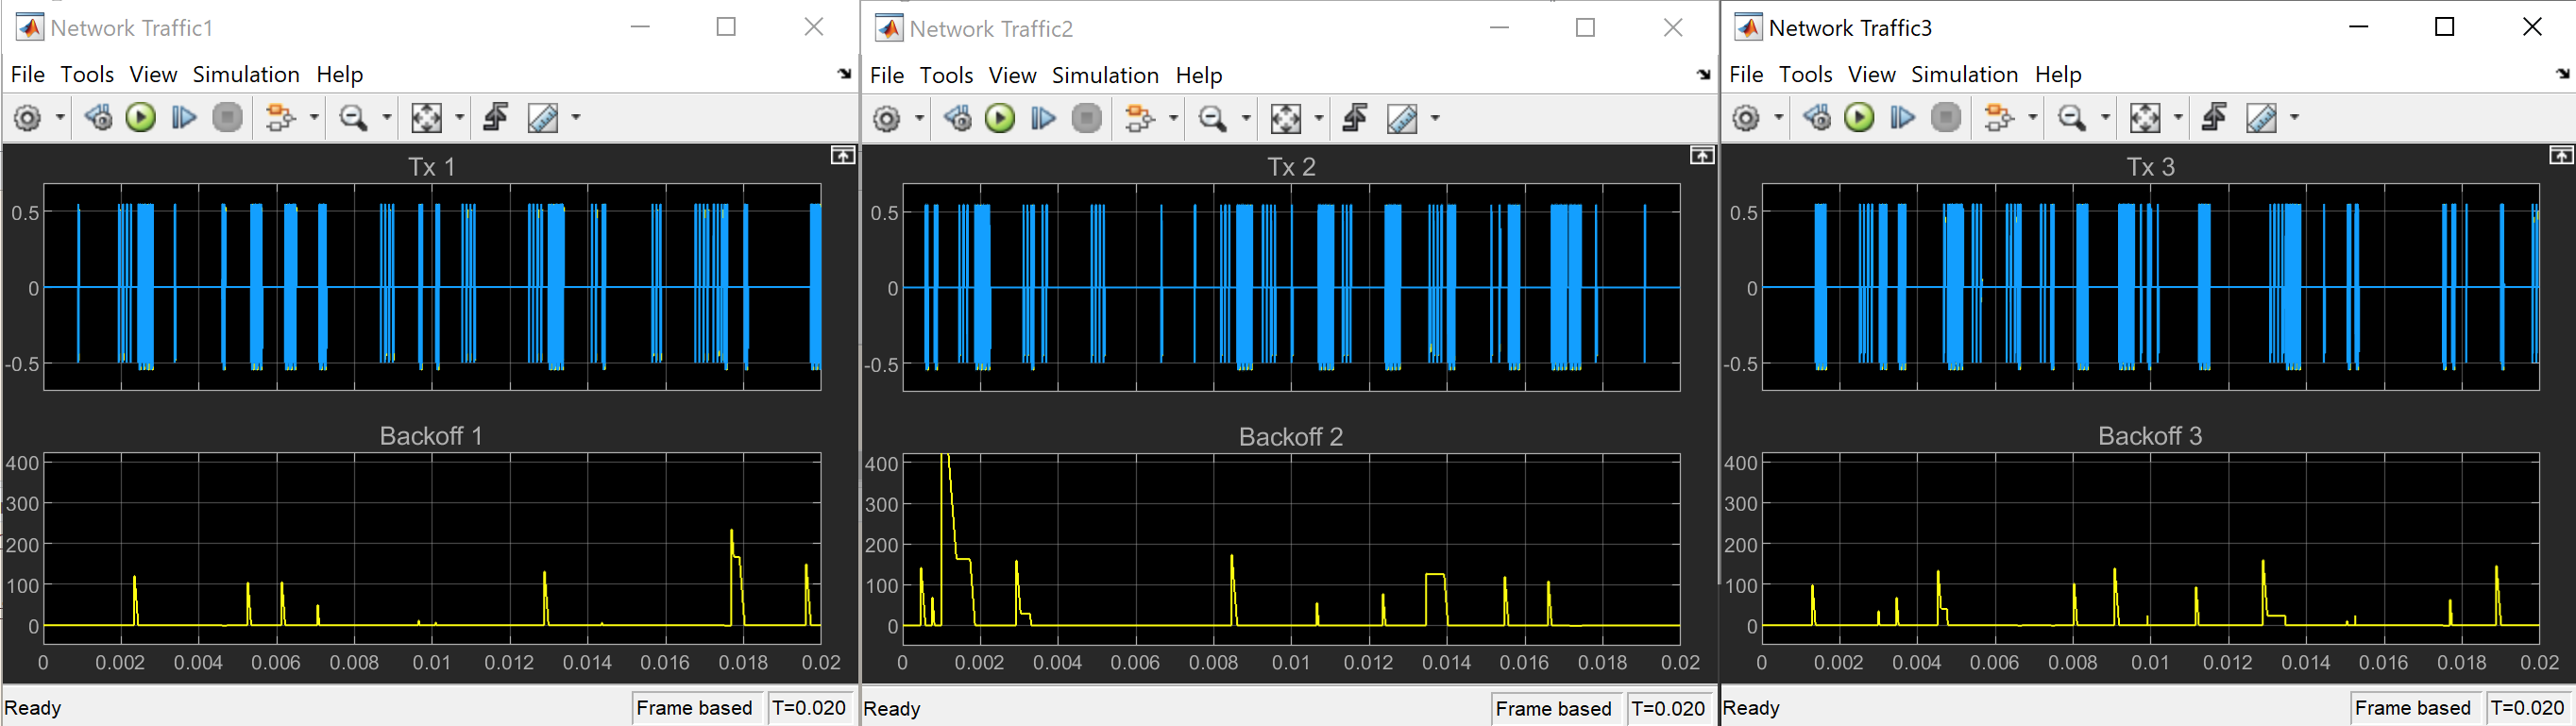

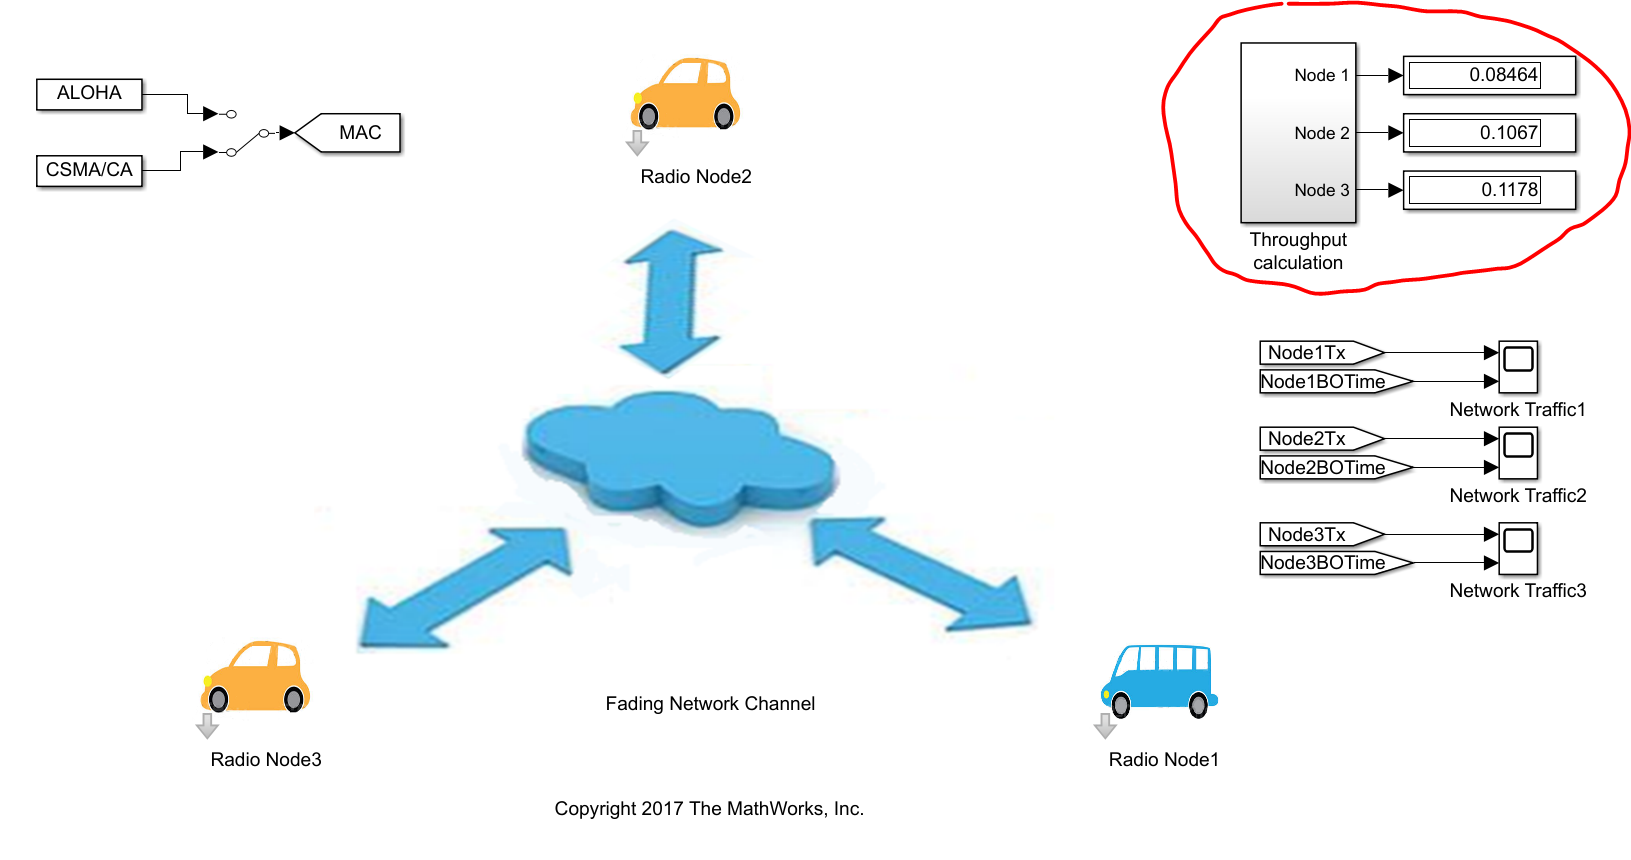

# P3-C-3

Modifying the SNR of white noise to 22 Eb/No and running the simulation again:

Using the ALOHA model:

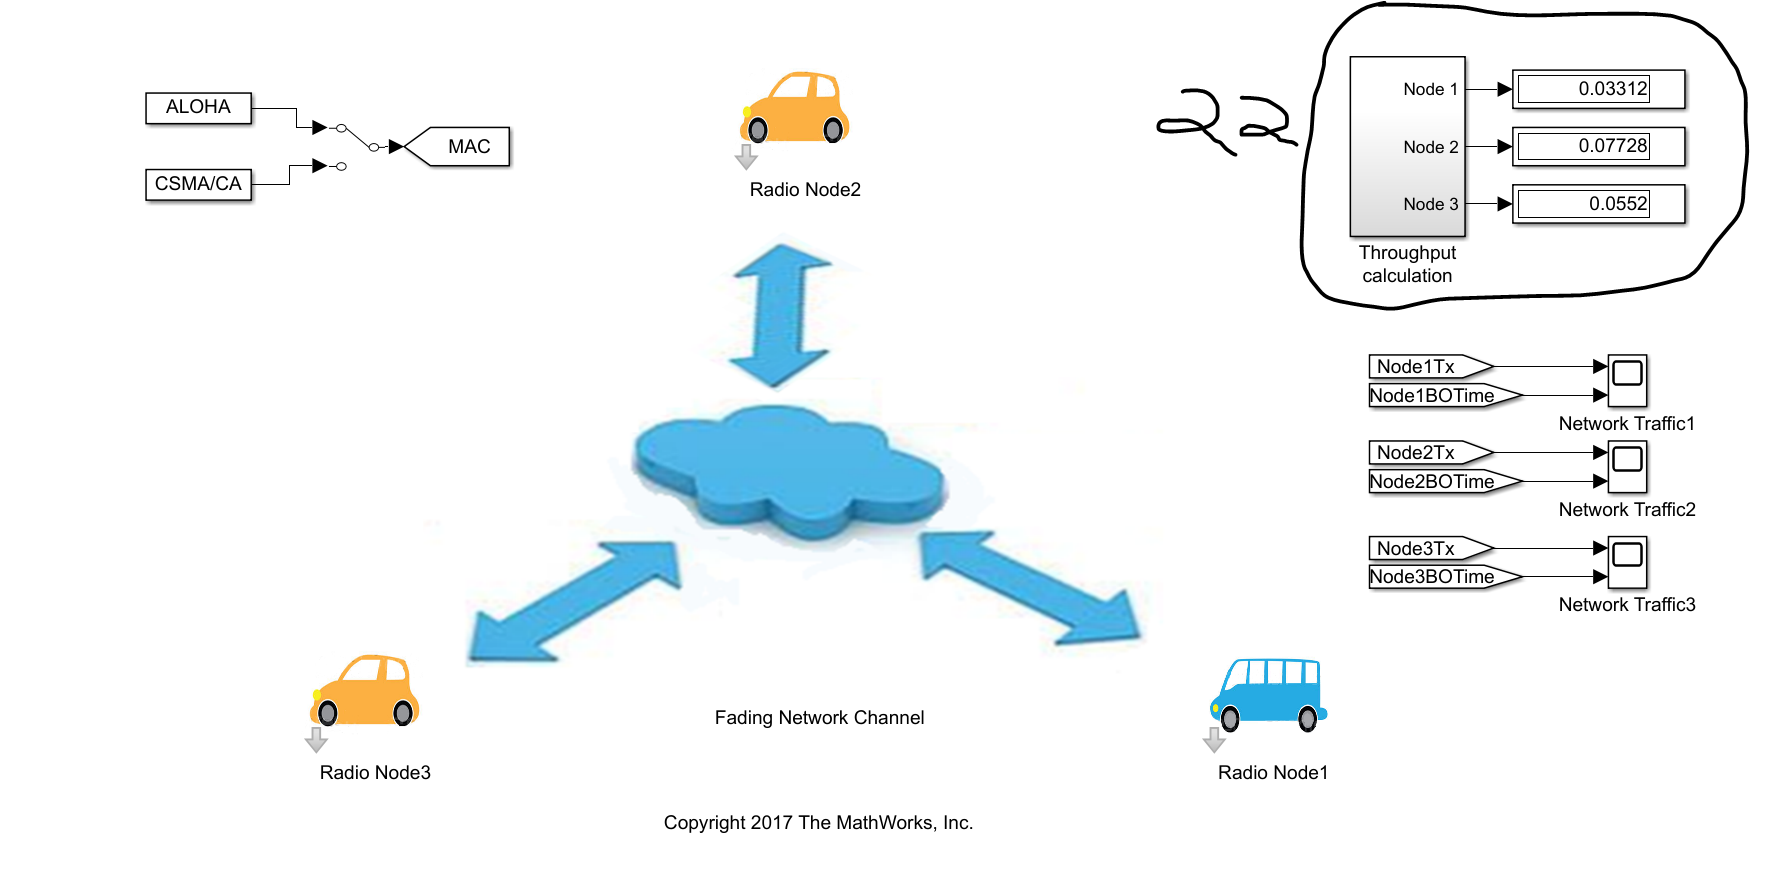

Using the CSMA/CA model:

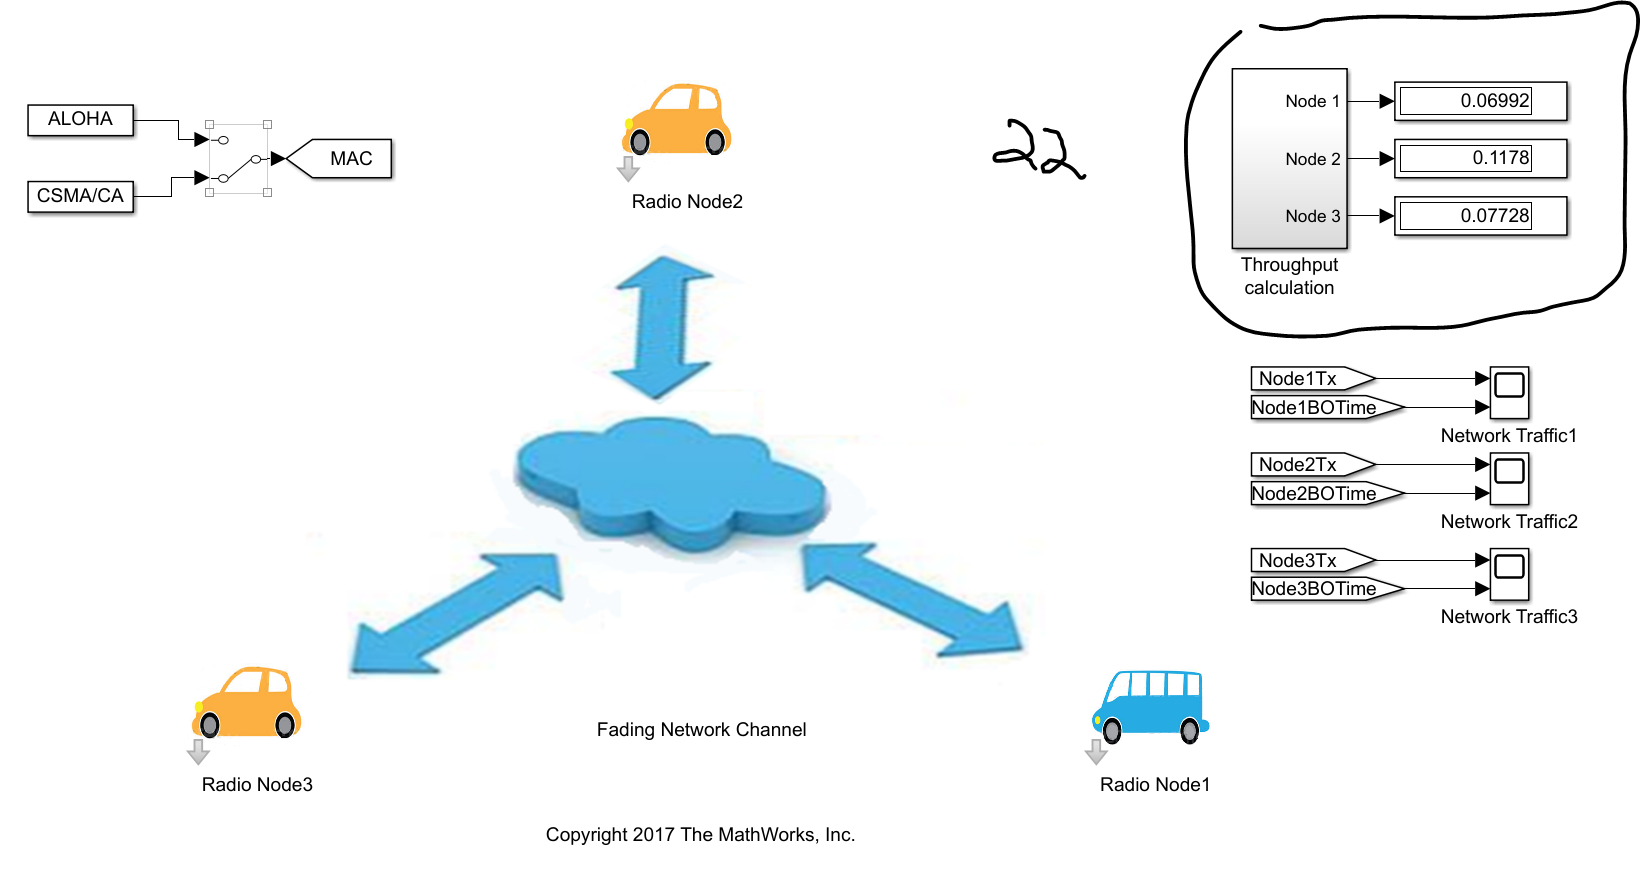

# P3-C-4

We observed a decreased throughput. This is expected because a lower signal-to-noise ratio means either the tranmitting signal has less power or the noise is stronger, and both will decrease the efficiency of tranmission. 

# P4

Two retranmission-based error controlling mechanism is stop-and-wait ARQ and continuous ARQ. 

With stop-and-wait ARQ, the receiver receives frame and sends ACK if no error or NAK if error. If NAK, sender will resend data. If no ACK or NAK, sender retranmits frame after timeout. If no ACK, sender resends data and receiver sends ACK and deletes duplicate frame.

With continuous ARQ, sender does not wait for ACKS before sending more data. Slidingwindow is the number of frames allowed to be unacknolowedged by receiver, and the number of frames that be sent depends on window size, which is agreed upon by sender and receiver at the beginning. 

# P5-A

question();
hostBits = ceil(log2(100))

hostBits = 7

Since the minimum of seven bits are needed, class A,B,and C can would all suffice. However, to acquire longer network ID bits availibilities, class C is enough.

# P5-B

If CIDR is used, then we can use the remaining bits as CIDR N bits:

cidrBits = 32-hostBits;
answer(cidrBits,"");

 ANSWER: 25 [] 


# P6

Computer#1→Interface1@Gateway:

- Source IP Address: IP1

- Destination IP Address: IP2

- MAC Address: MAC3

Interface2@Gateway→Computer#2:

- Source IP Address: IP1

- Destination IP Address: IP2

- MAC Address: MAC2

# P7-A

Subnetting help organize IP address within networks and organizations and allows organizations to distribute pool of IP addresses in subnets (depending upon organization structure).

# P7-B

subnetMask=[255,255,254,0];
subnetMask = dec2bin(subnetMask);
subnetMask = reshape(subnetMask',1,[])

subnetMask = '11111111111111111111111000000000'

subnetMaskBits = sum(subnetMask=='1');
hostIdBits = size(subnetMask,2)-subnetMaskBits;
answer(hostIdBits,"");

 ANSWER: 9 [] 


From the binary format of subnet mask, we can see the last 9 bits are not used for subnet address, which means the host ID can contain 9 bits.

# P7-C

netIdBits = 16;
subnetIdBits = subnetMaskBits-netIdBits;
answer(subnetIdBits,"");

 ANSWER: 7 [] 


# P7-D

maxSubnet = power(2,subnetIdBits);
answer(maxSubnet,"");

 ANSWER: 128 [] 


# P7-E

ip = [192,168,255,40];
ip = dec2bin(ip);
ip = reshape(ip',1,[]);
maskedIp = char((ip=='1'&subnetMask=='1')+'0')

maskedIp = '11000000101010001111111000000000'

maskedIp = reshape(maskedIp,log2(256),[])';
maskedIp = bin2dec(maskedIp)'

maskedIp =    192   168   254     0


# P8

The shortage of IPv4 is handled by Network Address Translation or IPv6. In NAT, some IP addresses are reused as a small pool of IP addresses to serve a large number of computers, which will not be globally unique. IPv6 on the other hand simply defines a new standard in RFC2460 which expands source and destination address fields from 32 bits to 128 bits. 

function table_out = transmit(dest,port,table_in)
%For Problem 2
    table_out = table_in;
    if(isKey(table_in,dest))
        fprintf("Cache hit from table.\n");
    else
        fprintf("Cache miss from table, create pair {%s,%s}.\n",dest,port);
        table_out(dest) = port;
    end
    disp([table_out.keys',table_out.values']);
end